# G11B / Luis Oriol Soler Cruz / Roger Gonzalez Herrera

LINK: 

## 0) Declare link sizes

L_1 = 4;
L_2 = 3;
L_3 = 2;
L_4 = 1;

## 1) DH-Std parameters and neighbouring homogeneous transformation matrices:

### Derive the DH-Std parameters

syms theta_1 theta_2 theta_3 real;

% [theta_i, d_i, a_i, alpha_i] std
DH_Standard = [theta_1,    theta_2,   theta_3;
               L_1+L_2,    0,         0;
               0,          L_3,       L_4;
               pi/2,       0,         0]'

$$DH\_Standard = \left(\begin{array}{cccc} \theta_{1} & 7 & 0 & \frac{\pi }{2}\\ \theta_{2} & 0 & 2 & 0\\ \theta_{3} & 0 & 1 & 0 \end{array}\right)$$

### Derive the Neighbouring homogeneus transformation matrices

% T_b_a = Rz(theta_i) * Dz(d_i) * Dx(a_i) * Rx(alpha_i)
T_1_0 = trotz(DH_Standard(1,1))*transl(0,0,DH_Standard(1,2))*transl(DH_Standard(1,3),0,0)*trotx(DH_Standard(1,4))

$$T\_1\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & 7\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_1 = trotz(DH_Standard(2,1))*transl(0,0,DH_Standard(2,2))*transl(DH_Standard(2,3),0,0)*trotx(DH_Standard(2,4))

$$T\_2\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 2\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 2\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_2 = trotz(DH_Standard(3,1))*transl(0,0,DH_Standard(3,2))*transl(DH_Standard(3,3),0,0)*trotx(DH_Standard(3,4))

$$T\_3\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## 2) Implement the forward kinematics T_0_3:

T_3_0 = T_1_0 * T_2_1 * T_3_2;

## 3) Calculate the result for joints (0,0,0), (0,pi/2,0), (0,pi/2,pi/6):

A_1 = subs(T_3_0, [theta_1,theta_2,theta_3], [0,0,0]);
A_1 = simplify(A_1)

$$A\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 3\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 7\\ 0 & 0 & 0 & 1 \end{array}\right)$$


B_1 = subs(T_3_0, [theta_1,theta_2,theta_3], [0,pi/2,0]);
B_1 = simplify(B_1)

$$B\_1 = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


C_1 = subs(T_3_0, [theta_1,theta_2,theta_3], [0,pi/2,pi/6]);
C_1 = simplify(C_1)

$$C\_1 = \left(\begin{array}{cccc} -\frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & -\frac{1}{2}\\ 0 & 0 & -1 & 0\\ \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 & \frac{\sqrt{3}}{2}+9\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## 4) Build the robot

### Generate links

L(1) = Link([0 L_1+L_2 0 pi/2])

 
L = 
Revolute(std):  theta=q1   d=7           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q2   d=0           a=2           alpha=0           offset=0          
Revolute(std):  theta=q3   d=0           a=1           alpha=0           offset=0          


L(2) = Link([0 0 L_3 0])

 
L = 
Revolute(std):  theta=q1   d=7           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q2   d=0           a=2           alpha=0           offset=0          
Revolute(std):  theta=q3   d=0           a=1           alpha=0           offset=0          


L(3) = Link([0 0 L_4 0])

 
L = 
Revolute(std):  theta=q1   d=7           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q2   d=0           a=2           alpha=0           offset=0          
Revolute(std):  theta=q3   d=0           a=1           alpha=0           offset=0          


### Generate robot

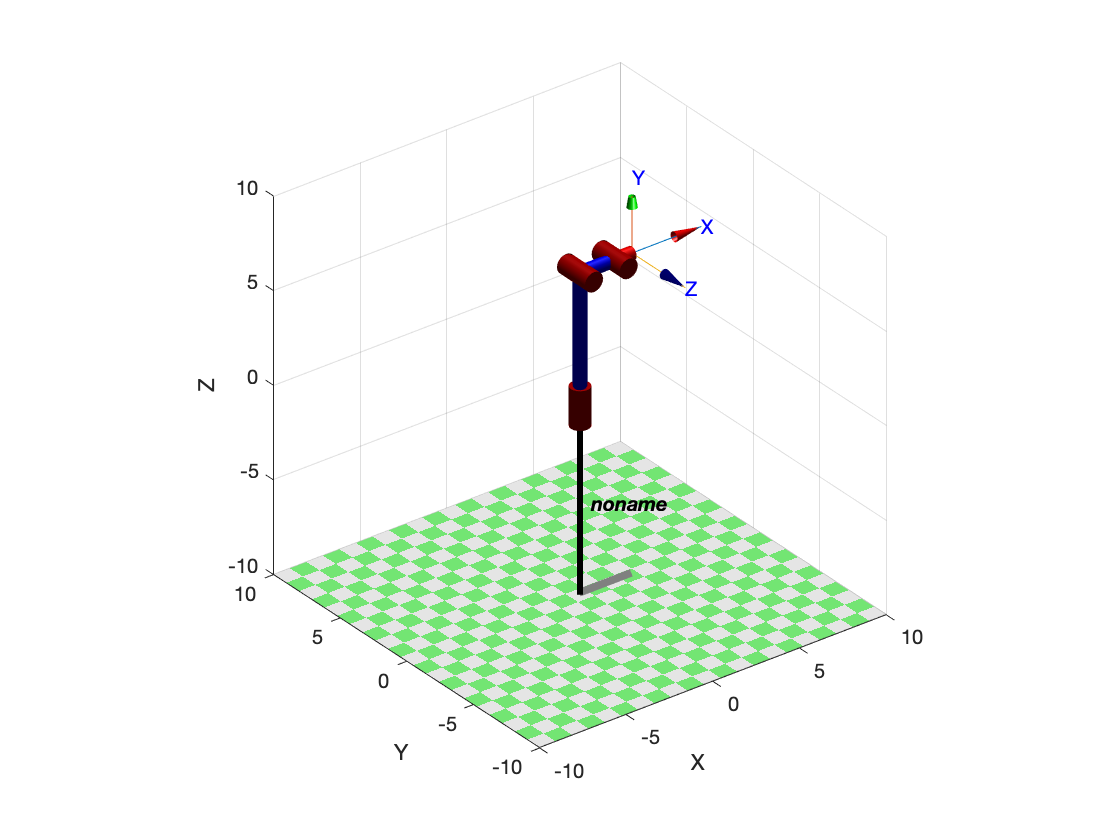

myRobot = SerialLink(L);
myRobot.plot([0 0 0]);

### Compare the neighboring matrices with the forward kinematics associated method

A_2 = myRobot.fkine([0 0 0])

 

A_2 = 
         1         0         0         3
         0         0        -1         0
         0         1         0         7
         0         0         0         1


B_2 = myRobot.fkine([0 pi/2 0])

 

B_2 = 
         0        -1         0         0
         0         0        -1         0
         1         0         0        10
         0         0         0         1


C_2 = myRobot.fkine([0 pi/2 pi/6])

 

C_2 = 
   -0.5000   -0.8660         0      -0.5
         0         0        -1         0
    0.8660   -0.5000         0     9.866
         0         0         0         1


### Compare with the RTB 3R Manipulator model: mdl_3link3d

mdl_3link3d
R3

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, fastRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


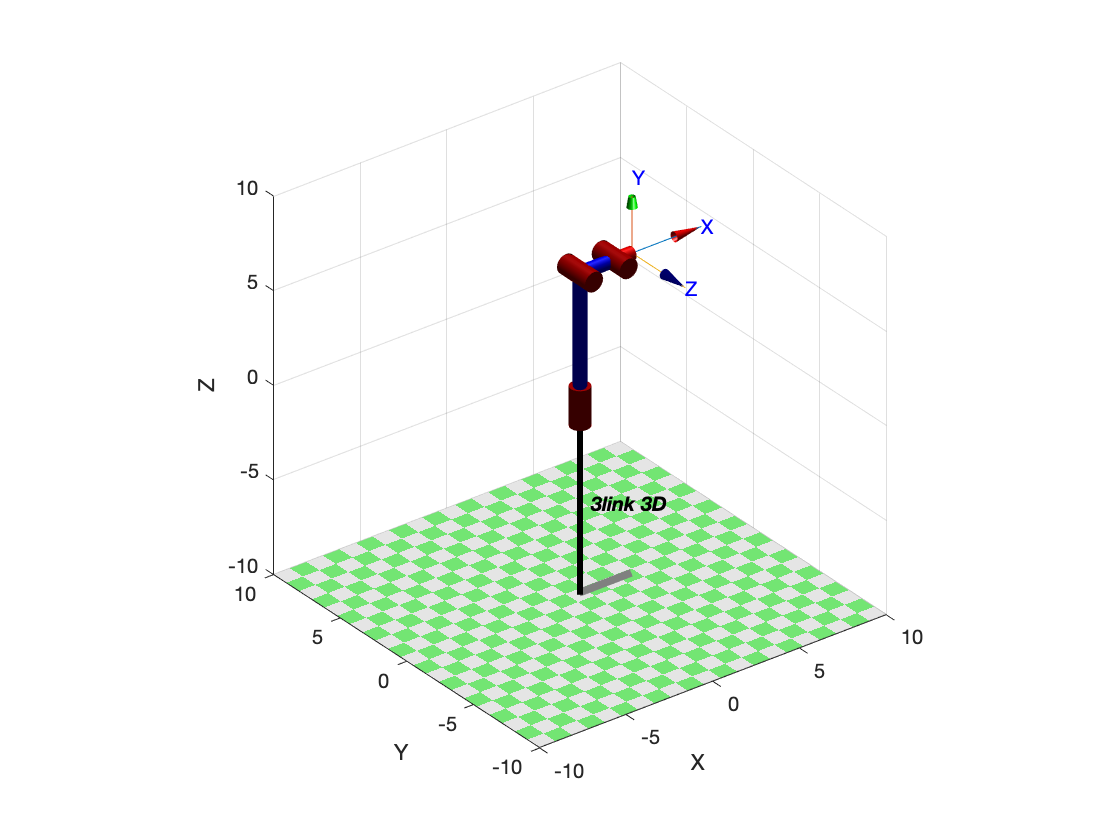

R3.links(1,1).d = 7;
R3.links(1,2).a = 2;
R3.links(1,3).a = 1;
R3.plot([0 0 0]);


A_3 = R3.fkine([0 0 0])

 

A_3 = 
         1         0         0         3
         0         0        -1         0
         0         1         0         7
         0         0         0         1


B_3 = R3.fkine([0 pi/2 0])

 

B_3 = 
         0        -1         0         0
         0         0        -1         0
         1         0         0        10
         0         0         0         1


C_3 = R3.fkine([0 pi/2 pi/6])

 

C_3 = 
   -0.5000   -0.8660         0      -0.5
         0         0        -1         0
    0.8660   -0.5000         0     9.866
         0         0         0         1
